clc;close all;clear;

**Question1**

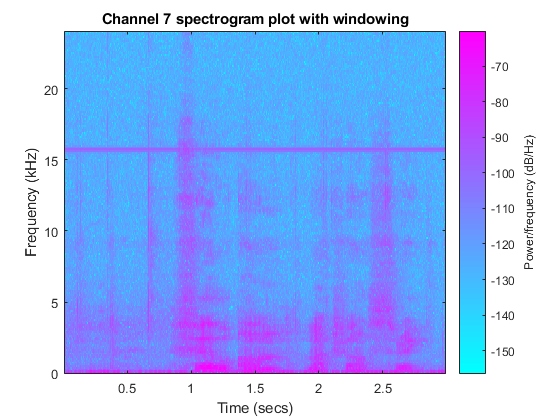


win_size = 0.004;
fft_overlap = 0.5;
[signal_C7, Fs] = audioread('c7Mic3Intro.wav');
hop_size = Fs*win_size;
nfft = hop_size/fft_overlap;
noverlap = nfft-hop_size;
w = sqrt(hann(nfft));
figure
spectrogram(signal_C7, w ,noverlap, nfft, Fs, 'yaxis' );
colormap cool;
title('Channel 7 spectrogram plot with windowing');

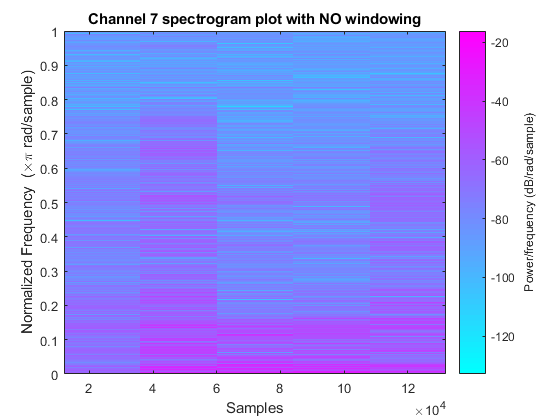

figure
spectrogram(signal_C7, Fs, 'yaxis' );
colormap cool;
title('Channel 7 spectrogram plot with NO windowing');

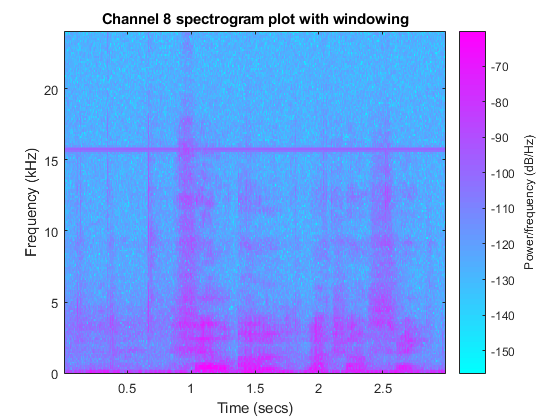

[signal_C8, Fs_8] = audioread('c7Mic3Intro.wav');
figure
spectrogram(signal_C8, w ,noverlap, nfft, Fs_8, 'yaxis' );
colormap cool;
title('Channel 8 spectrogram plot with windowing');

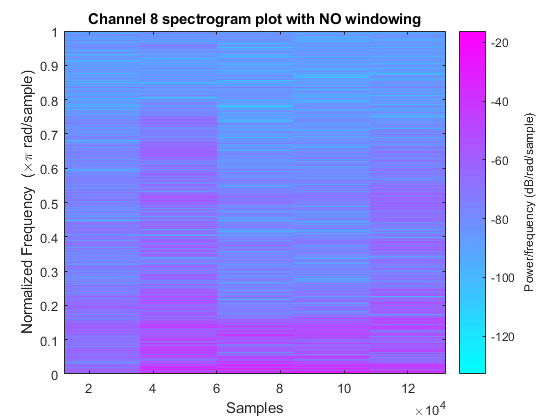

figure
spectrogram(signal_C8, Fs_8, 'yaxis' );
colormap cool;
title('Channel 8 spectrogram plot with NO windowing');

**Question2**

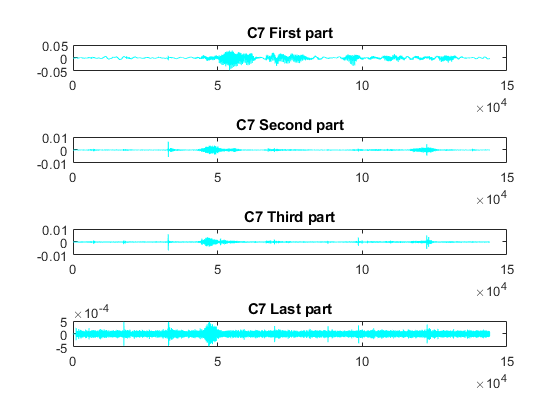

[data7,Fs7]= audioread('c7Mic3Intro.wav');
fnorm1_C7 = 1/4; 

data_1 = filter(LP,data7); 
data_2 = filter(bp1,data7); 
data_3 = filter(bp2,data7); 
data_4 = filter(HP,data7);
figure
 subplot(4,1,1), plot(data_1,'c'), title('C7 First part')
 subplot(4,1,2), plot(data_2,'c'), title('C7 Second part')
 subplot(4,1,3), plot(data_3,'c'), title('C7 Third part')
 subplot(4,1,4), plot(data_4,'c'), title('C7 Last part')

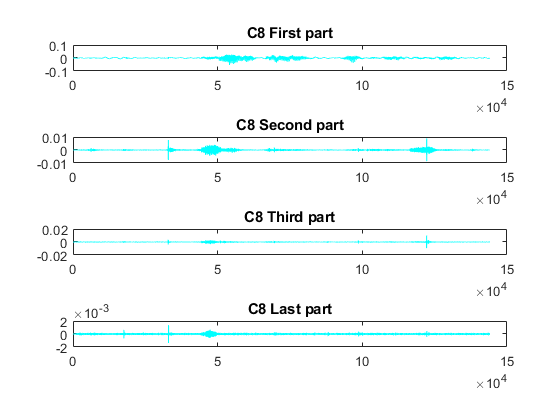

[data8,Fs8]= audioread('c8Mic3Intro.wav');

data_5 = filter(LP,data8); 
data_6 = filter(bp1,data8); 
data_7 = filter(bp2,data8); 
data_8 = filter(HP,data8);
figure
 subplot(4,1,1), plot(data_5,'c'), title('C8 First part')
 subplot(4,1,2), plot(data_6, 'c'), title('C8 Second part')
 subplot(4,1,3), plot(data_7 , 'c'), title('C8 Third part')
 subplot(4,1,4), plot(data_8, 'c'), title('C8 Last part')

**Question3**

 All_data = zeros(144001,8);
 All_data(:,1) = data_1;
 All_data(:,2) = data_2;
 All_data(:,3) = data_3;
 All_data(:,4) = data_4;
 All_data(:,5) = data_5;
 All_data(:,6) = data_6;
 All_data(:,7) = data_7;
 All_data(:,8) = data_8;
 
 All_Chunked_channels = zeros(256,562,8);
 for  data= 1:8
     for chunk= 1:562
         start_index = 256*chunk-255;
         end_index = 256*chunk;
         All_Chunked_channels(:,chunk,data) = All_data(start_index:end_index,data);
     end
 end


**Question4**

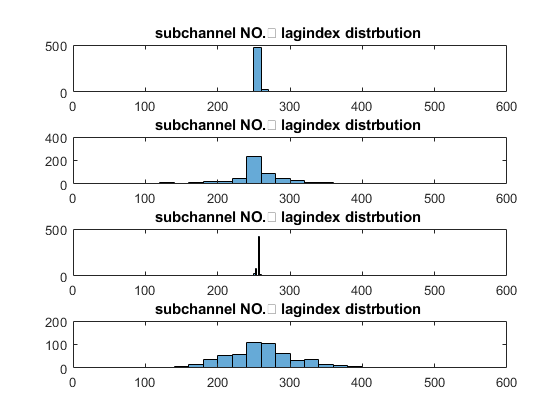

 correlation_same_subchannels = zeros(562,4);
 for sc = 1:4
     for chunk = 1:562
         [~,correlation_same_subchannels(chunk,sc)] = max(abs(xcorr(All_Chunked_channels(:,chunk,sc),All_Chunked_channels(:,chunk,sc+4))));
     end
 end
figure
for i = 1:4
 subplot(4,1,i),histogram(correlation_same_subchannels(:,i)), title(['subchannel NO.',i,' lagindex distrbution ']),xlim([0  600]);
end

**Question5**

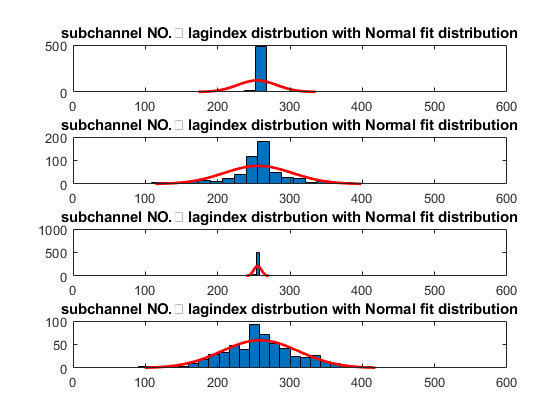

figure
for i = 1:4
 subplot(4,1,i),histfit(correlation_same_subchannels(:,i)), title(['subchannel NO.',i,' lagindex distrbution with Normal fit distribution']),xlim([0  600]);
end

 first_channel = fitdist(correlation_same_subchannels(:,1),'Normal');
 display(first_channel);

first_channel =   NormalDistribution

  Normal distribution
       mu = 254.532   [252.296, 256.768]
    sigma = 26.9818   [25.4913, 28.6589]


 second_channel = fitdist(correlation_same_subchannels(:,2),'Normal');
 display(second_channel);

second_channel =   NormalDistribution

  Normal distribution
       mu = 256.089   [252.16, 260.018]
    sigma = 47.4203   [44.8007, 50.3678]


 third_channel = fitdist(correlation_same_subchannels(:,3),'Normal');
 display(third_channel);

third_channel =   NormalDistribution

  Normal distribution
       mu = 255.171   [254.736, 255.606]
    sigma = 5.24678   [4.95693, 5.5729]


 last_channel = fitdist(correlation_same_subchannels(:,4),'Normal');
 display(last_channel);

last_channel =   NormalDistribution

  Normal distribution
       mu = 258.669   [254.27, 263.068]
    sigma = 53.0895   [50.1567, 56.3894]
